# input data

file='C:\Users\PhotonUser\My Files\Temporary Files\Lab4-3BodePlot.txt';
fileID=fopen(file);
textstuff=textscan(fileID, '%s %s %s','Delimiter','\t');
fclose(fileID);

## organize and separate frequency data

freq=textstuff{1,1};
freq=string(freq);
freq=freq(4:36);
freq=str2double(freq);
freq=2.*pi.*freq;

## organize and separate gain data

gain=textstuff{1,2};
gain=string(gain);
gain=gain(4:36);
gain=str2double(gain);

## organize and separate phase shift data

phase=textstuff{1,3};
phase=string(phase);
phase=phase(4:36);
phase=str2double(phase);

## measured data

f=[50.79,152.37,507.9,1523.7,5079];
f=2.*pi.*f;
g=[0.184,0.286,0.6498,0.925,0.999];
g=20*log10(g);
p=[27.79,41.688,36.569,16.456,9.14];

## theoretical gain data

ft=linspace(50.79,7618.5,100);
ft=2.*pi.*ft;
n=ft.*0.047./150;
wlr=ft.*0.047./150;
wlr2=(wlr).^2;
dur=1+wlr2;
d=sqrt(dur);
il=n./d;
tg=20.*log10(il);

## theoretical phase shift data

it=2.*pi.*ft.*0.047./150;
tpr=(pi./2)-atan(it);
tp=tpr.*180./pi;

## gain plot

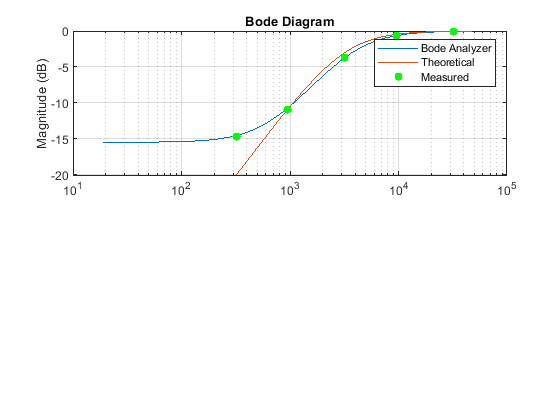

subplot(2,1,1);
semilogx(freq,(gain),'DisplayName','Bode Analyzer')
hold on
plot(ft,tg,'DisplayName','Theoretical')
hold on
scatter(f(1),g(1),'filled','g','DisplayName','Measured')
hold on
scatter(f(2),g(2),'filled','g')
hold on
scatter(f(3),g(3),'filled','g')
hold on
scatter(f(4),g(4),'filled','g')
hold on
scatter(f(5),g(5),'filled','g')
hold on
grid on
ylabel('Magnitude (dB)')
title('Bode Diagram')
legend('Bode Analyzer','Theoretical','Measured')
hold off

## phase shift plot

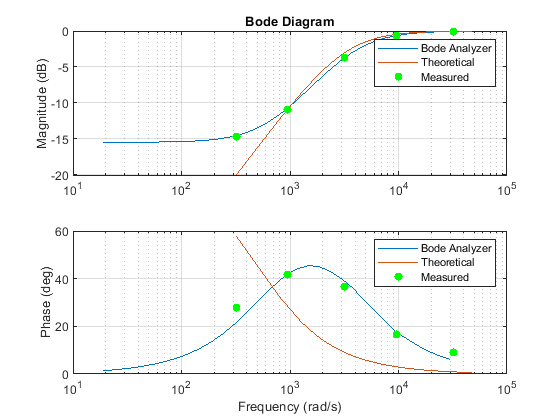

subplot(2,1,2)
semilogx(freq,phase,'DisplayName','Bode Analyzer')
hold on 
plot(ft,tp,'DisplayName','Theoretical');
scatter(f(1),p(1),'filled','g','DisplayName','Measured')
hold on
scatter(f(2),p(2),'filled','g')
hold on
scatter(f(3),p(3),'filled','g')
hold on
scatter(f(4),p(4),'filled','g')
hold on
scatter(f(5),p(5),'filled','g')
hold on
grid on 
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Bode Analyzer','Theoretical','Measured')